# lora sim script

## lora parameters

%clear;
SF=7; %spreading factor 7-12
Fs=125e3;%samplingrate = BW
SPS=2^SF;%samples per symbol



## sim parameters

%data
numSym=round(10000/SF);
randomData=true;
%channel
perfectChannel=false;%no doppler or awgn
maxDopplerShift=0;
flatDoppler=true;%true: apply same shift to entire signal, false: gradient from +maxShift to -maxShift over length of signal
maxSNR=10; %signal to noise ratio in dB
%loops
nLoops=20;
loopSNR=true;
SNRstepsize=2;
loopDoppler=false;

plotSpectrogram=true;

## tx

%generate data
dataLength=numSym*SF;% SF bits per symbol
if randomData
    messageBits= randi([0 1],dataLength,1);
else
    messageBits=ones(dataLength,1);
end
%generate lora signal
loraSignal=generateLoraSignal(messageBits,SF,numSym);

decimalSymbols =     15    13    54    55    33    87    99    66   124    47   103   107    14     0    14    56    59    30    79    35    75    13    61    24    61    71    61    12    56    14   106    24    17    65    21    74     6    17    56     0   127    77    31   116   106    34    20    29    53    75


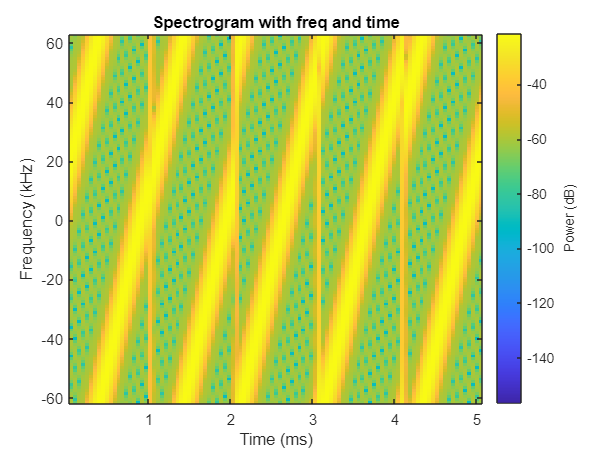

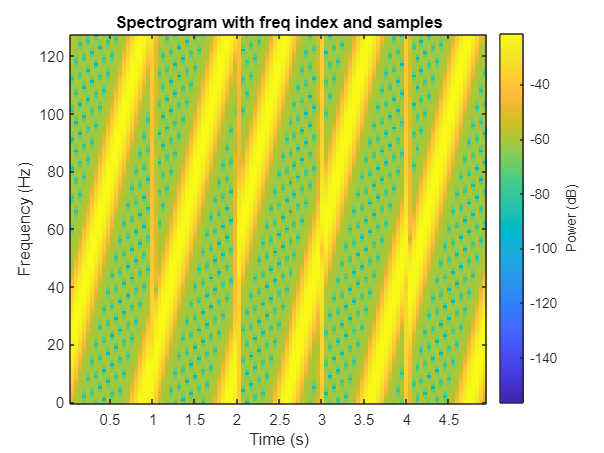


if plotSpectrogram
    %spectroram of first 5 symbols
    figure
    windowLength=round((SPS)/10);
    spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
    title('Spectrogram with freq and time')
    figure
    spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
    title('Spectrogram with freq index and samples')
end

## channel & rx

%channel
for counter=1:nLoops
    if perfectChannel
       rxSignal=loraSignal;
    else
        if loopSNR
            rxSignal=(awgn(loraSignal,maxSNR-(counter-1)*SNRstepsize,'measured'));
        else
            rxSignal=(awgn(loraSignal,maxSNR,'measured'));
        end
        %snr
     end
    %rx
    decodedBits=demodulateLoraSignal(rxSignal,SF,numSym);
    errors(counter)=sum(messageBits~=decodedBits);
end

## ber


lora_ber7=errors/dataLength

lora_ber7 =          0         0         0         0         0         0         0         0         0    0.0011    0.0133    0.1049    0.2253    0.3610    0.4225    0.4493    0.4815    0.4822    0.4999    0.4864


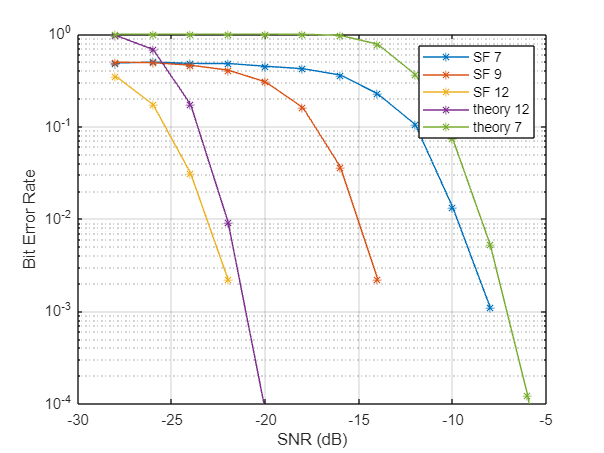

% lora_ber9=errors/dataLength
% lora_ber12=errors/dataLength

if loopSNR
    figure
    
    SNRvec=flip((maxSNR-(nLoops-1)*SNRstepsize):SNRstepsize:maxSNR);
    semilogy(SNRvec',lora_ber7,'-*')
    hold on
    semilogy(SNRvec',lora_ber9,'-*')
    semilogy(SNRvec',lora_ber12,'-*')
    %theoryBer12=qfunc((log(SF)/log(12))/sqrt(2)*(SNRvec+10*log10((2^SF)/SF)));
    theoryBer7=qfunc((log(SF)/log(12))/sqrt(2)*(SNRvec+10*log10((2^SF)/SF)));
    semilogy(SNRvec',theoryBer12,'-*')
     semilogy(SNRvec',theoryBer7,'-*')
    grid on
    xlabel('SNR (dB)')
    ylabel('Bit Error Rate')
    ylim([10e-5 1])
    legend('SF 7','SF 9','SF 12','theory 12','theory 7')
    
end